# Problem 1:

Matlab function "circonv" is included at the end of this report under Appendix A.

y = circonv(x,h,N);

This functions has 3 inputs:

1- x, the input signal

2- h, the impulse response of the filter

3- N, the length of the circular convolution

Also, input "N" can be used to alter the function to linear convolution. Since length of circular convolution cannot be zero, if N is set to zero, my "circonv" function will do a circular convolution of length M+P-1 (M is length of x and P is length of h), which is equivalent to linear convolution.

The output will be a vector of length N (or length M+P-1 in case N is 0), which is circular convolution (or linear convolution if N is set to 0) of vectors x and h.

# Problem 2:

#### **a)**

Stem plot of one period of the output is illustrated in Figure 1.

xa = [1 1 1 1];
ha = [1 2 3];
N=4;
ya = circonv(xa,ha,N);

disp('circonv(x,h,N)')

circonv(x,h,N)


disp(['x = [' num2str(xa) ']'])

x = [1  1  1  1]


disp(['h = [' num2str(ha) ']'])

h = [1  2  3]


disp(['N = ' num2str(N)])

N = 4


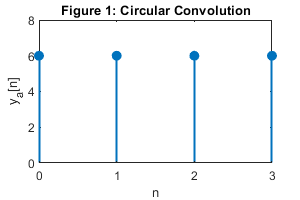

figure
stem((1:4)-1,ya,'filled','LineWidth',1.5)
ylim([0,8])
xlabel('n')
ylabel('y_a[n]')
set(gcf,'position',[50,50,300,200])
title('Figure 1: Circular Convolution')

**b)**

Stem plot of the output is illustrated in Figure 2.

xb = [1 1 1 1];
hb = [1 2 3];
yb = circonv(xb,hb,0);

disp('circonv(x,h,N)')

circonv(x,h,N)


disp(['x = [' num2str(xb) ']'])

x = [1  1  1  1]


disp(['h = [' num2str(hb) ']'])

h = [1  2  3]


disp('N = 0' )

N = 0


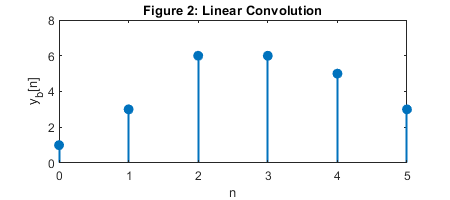

figure
stem((1:6)-1,yb,'filled','LineWidth',1.5)
ylim([0,8])
xlabel('n')
ylabel('y_b[n]')
set(gcf,'position',[50,50,450,200])
title('Figure 2: Linear Convolution')

**c)**

Stem plot of one period of the output is illustrated in Figure 3.

xc = [1 3 6 2 8];
hc = [2 9 5 3];
N=6;
yc = circonv(xc,hc,N);

disp('circonv(x,h,N)')

circonv(x,h,N)


disp(['x = [' num2str(xc) ']'])

x = [1  3  6  2  8]


disp(['h = [' num2str(hc) ']'])

h = [2  9  5  3]


disp(['N = ' num2str(N)])

N = 6


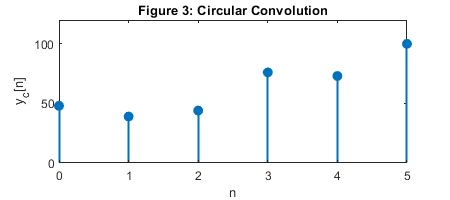

figure
stem((1:6)-1,yc,'filled','LineWidth',1.5)
ylim([0,120])
xlabel('n')
ylabel('y_c[n]')
set(gcf,'position',[50,50,450,200])
title('Figure 3: Circular Convolution')

# Problem 3:

Matlab function "ola" is included at the end of this report under Appendix B.

load('MP2data')
N=100;
y = ola(x,h,N);

This functions has 3 inputs:

1- x, the input signal

2- h, the impulse response of the filter

3- N, the length of the DFT

Length of the blocks are internally calculated as L=N+1-P, in which P is the length of impulse response.

The output "y" is a vector with the same length as input signal "x", and "y" is result of convolving "x" by "h".

# Problem 4:

Input parameters of ola are "x", and "h" which come from the given data file, and N has been set to 100.

load('MP2data')
N=100;
y = ola(x,h,N);

**a)**

h[n] is a delayed sinc function (figure 4), as a result it approximates a lowpass filter (figure 5).

Also, a comparison between input signal x[n] (figure 6a) and convolved signal (figure 6b) shows that only a low frequency has remained and all higher frequencies are removed, which resulted from convolving with lowpass filter.

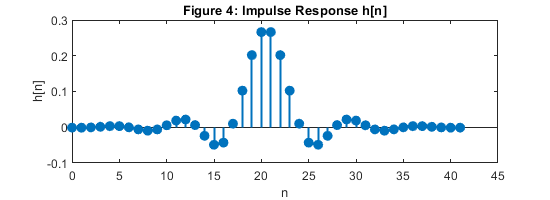

load('MP2data')

figure
stem((1:42)-1,h,'filled','LineWidth',1.5)
ylim([-0.1,0.3])
xlim([0 45])
xlabel('n')
ylabel('h[n]')
set(gcf,'position',[50,50,550,200])
title('Figure 4: Impulse Response h[n]')

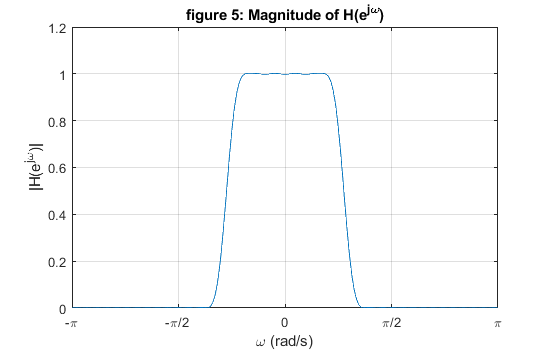


H = fft(h,1024);
figure,
plot(linspace(-pi,pi,1024),fftshift(abs(H)))
xlim([-pi,pi])
grid on
xticks([-pi -pi/2 0 pi/2 pi])
set(gca,'XTickLabel',{'-\pi','-\pi/2','0','\pi/2','\pi'})
xlabel('\omega (rad/s)')
ylabel('|H(e^j^\omega)|')
title('figure 5: Magnitude of H(e^j^\omega)')
ylim([0,1.2])
set(gcf,'position',[50,50,550,350])

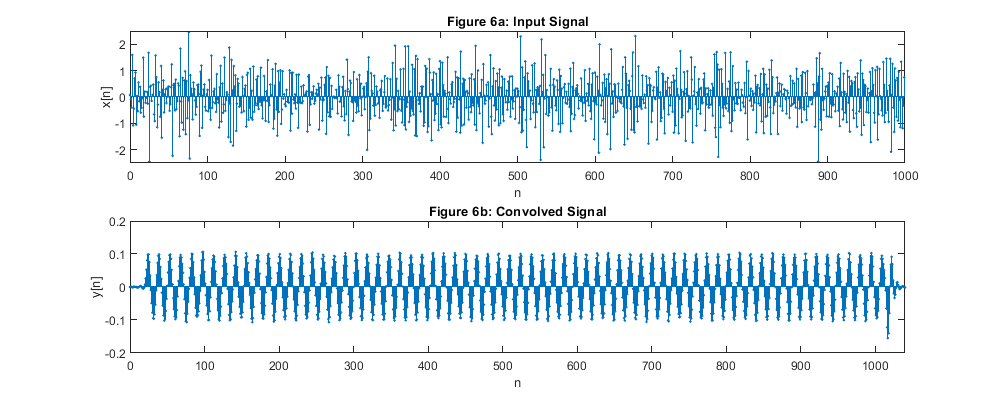

figure,
subplot(2,1,1)
stem(0:length(x)-1,x,'filled','LineWidth',0.5,'MarkerSize',1.5)
ylim([-2.5,2.5])
xlabel('n')
ylabel('x[n]')
title('Figure 6a: Input Signal')
subplot(2,1,2)
stem(0:length(y_ola)-1,y_ola,'filled','LineWidth',0.5,'MarkerSize',1.5)
ylim([-0.2,0.2])
xlim([0,1040])
xlabel('n')
ylabel('y[n]')
title('Figure 6b: Convolved Signal')
set(gcf,'position',[50,50,1000,400])

error = mean((y_ola-y_conv).^2);
disp(['Average error between "conv" and "ola" = ' num2str(error)])

Average error between "conv" and "ola" = 6.7514e-33


**b)**

Range for block length can be 1 to 1000, and since L=N+1-P, and P=42, range for N (DFT size) is 42 to 1043. Setting N greater than 1043 pads both x and h with unnecessary zeros.

**c)**

Both "ola" and "conv" functions are used to convolve given input signal and impulse responce. An error term equal to average of square of element-wise defferences was defined to compare the results.

y_ola=ola(x,h,100);
y_conv=conv(x,h);

error = mean((y_ola-y_conv).^2);
disp(['Average error between "conv" and "ola": ' num2str(error)])

Average error between "conv" and "ola": 6.7514e-33


Small error is confirming that "ola" is working as intended.

# Appendix A:

function y=circonv(x,h,N)

if N == 0
    N = length(x)+length(h)-1;
end
    
X = fft(x,N);
H = fft(h,N);
Y = X.*H;
y = ifft(Y,N);

end

# Appendix B:

function y=ola(x,h,N)

M = length(x);
P = length(h);
L = N+1-P;
r = mod(M,L);
% Adding zeros in case length of a is not a multiplier of block length
if r ~= 0
    x = [x zeros(1,L-r)];
    M = length(x);
end
y = zeros(1,M+P-1);

H = fft(h,L+P-1);
i = 1;
while i<=M
    Xr = fft(x(i:i+L-1),L+P-1);
    Yr = H.*Xr;
    yr = ifft(Yr,L+P-1);
    y(i:i+L+P-2) = y(i:i+L+P-2)+yr;
    i=i+L;
end
%removing extra data resulting from zero padding the input signal
if r ~= 0
    y(end-(L-r-1):end) = [];
end
end